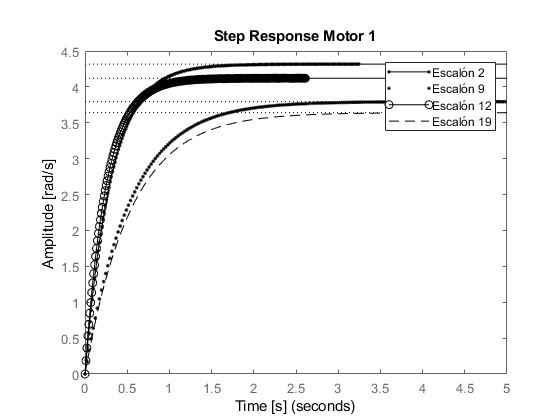

% PrimerEjecutar Motor1 y Motor2
clear all
load M1Seleccion.mat
load M2Seleccion.mat
% s=tf('s')

EscalonesM1 = [2,9,12,19];
EscalonesM2 = [2,9,12,19];

[A1,B1,C1,D1]=M1Funcion{EscalonesM1};
step(A1,'.-k',-B1,'.k',-C1,'o-k',D1,'--k');
title('Step Response Motor 1')
xlabel('Time [s]')
ylabel('Amplitude [rad/s]')
legend('Escalón 2','Escalón 9','Escalón 12','Escalón 19')

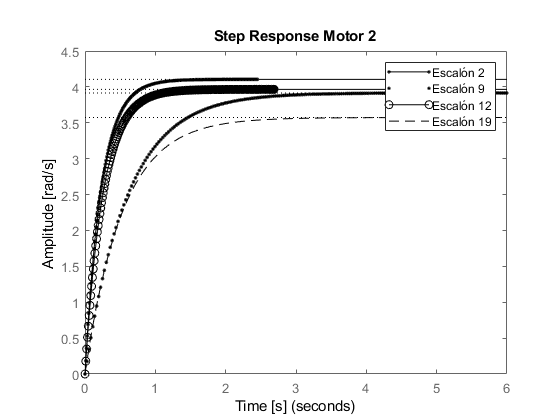

[A2,B2,C2,D2]=M2Funcion{EscalonesM2};
step(A2,'.-k',-B2,'.k',-C2,'o-k',D2,'--k');
title('Step Response Motor 2')
xlabel('Time [s]')
ylabel('Amplitude [rad/s]')
legend('Escalón 2','Escalón 9','Escalón 12','Escalón 19')

%  los tiempos de establecimiento son similares para aceleraciones
%  o desaceleraciones

RangosM1=M1y0(EscalonesM1+1)-M2y0(EscalonesM1)

RangosM1 =     4.4090   -3.3085   -4.4090    3.3070


RangosM2=M2y0(EscalonesM2+1)-M2y0(EscalonesM2)

RangosM2 =     4.0620   -4.2542   -3.8680    3.6750



% c2d(A1/s,0.005,'tustin')


Filtros elegidos

el filtro que corte al resto

% Imprime el indice del filtro mas rapido
[M1na,idxM1]=min(M1Tao(EscalonesM1))

M1na = 0.2475

idxM1 = 3



[M2na,idxM2]=min(M2Tao(EscalonesM2))

M2na = 0.2325

idxM2 = 1

Rango de tiempo de muestreo

[0.2,0.6]*M1na

ans =     0.0495    0.1485



[0.2,0.6]*M2na

ans =     0.0465    0.1395
